Fuzzy Logic Home EMS controller

Load Siulink Model

cd C:\dev\WPS3-EMS\FuzzyLogicController\
model = 'Training_Model_compactHEMS';
load_system(model)
%out_Hems = sim(model)
%plot_results_HEMS(out_Hems)

## Create FIS Tree Controller Structure

% If already have a Fis use
% fis_Current = readfis(fileName)


% Define membership function names for the input variables.
% Input MF of variables
mf_SOC = ["Min","Low","Medium","High","Max"]; % Low, Medium, High
mf_Pnet = ["RES>>","Load>>"]; % [- 0 +] P_net = P_Load-P_RES :: Negative (High PV), Zero, Positive (High Load)
%mf_Price = ["Low","High"]; % Low , High
% Output MF
mf_Pbatt = ["CH","HOLD","DC"]; % % [- 0 +] 

clear fis_Current

% Create first FIS.
fis_Current = mamfis('Name','FIS Current','NumInputs',2,'NumOutputs',1, ...
    'NumInputMFs',[length(mf_SOC) length(mf_Pnet)],'NumOutputMFs',length(mf_Pbatt));
% convert to Sugeno 
fis_Current = convertToSugeno(fis_Current);

% Configure input and output variables.
% Input 1 SOC
SOC_range = [battery_min_soc battery_max_soc];
fis_Current = updateInput(fis_Current,1,'SOC',SOC_range , mf_SOC);
fis_Current.Inputs(1).MembershipFunctions(1).Type = 'linzmf';% MIN
fis_Current.Inputs(1).MembershipFunctions(1).Parameters = [SOC_range(1) SOC_range(1)+1];
fis_Current.Inputs(1).MembershipFunctions(2).Type = 'trimf'; %LOW
fis_Current.Inputs(1).MembershipFunctions(2).Parameters = [SOC_range(1)  SOC_range(1)+15 SOC_range(1)+30];
fis_Current.Inputs(1).MembershipFunctions(3).Type = 'trimf'; % MED
fis_Current.Inputs(1).MembershipFunctions(3).Parameters = [40 60 80];
fis_Current.Inputs(1).MembershipFunctions(4).Type = 'trimf'; % HIGH
fis_Current.Inputs(1).MembershipFunctions(4).Parameters = [SOC_range(2)-30 SOC_range(2)-15 SOC_range(2)];
fis_Current.Inputs(1).MembershipFunctions(5).Type = 'linsmf'; % MAX
fis_Current.Inputs(1).MembershipFunctions(5).Parameters = [SOC_range(2)-1 SOC_range(2)];


% Input 2 Net Power
Net_power_range = [-1 1] ;%  
fis_Current = updateInput(fis_Current,2,'Pnet',Net_power_range, mf_Pnet);
fis_Current.Inputs(2).MembershipFunctions(1).Type = 'linzmf';
fis_Current.Inputs(2).MembershipFunctions(1).Parameters = [Net_power_range(1) 0.5];
fis_Current.Inputs(2).MembershipFunctions(2).Type = 'linsmf';
fis_Current.Inputs(2).MembershipFunctions(2).Parameters = [-0.5 Net_power_range(2)];

% Input 3 price
%fis_Current = updateInput(fis_Current,3,'Price',[0 1],mf_Price);

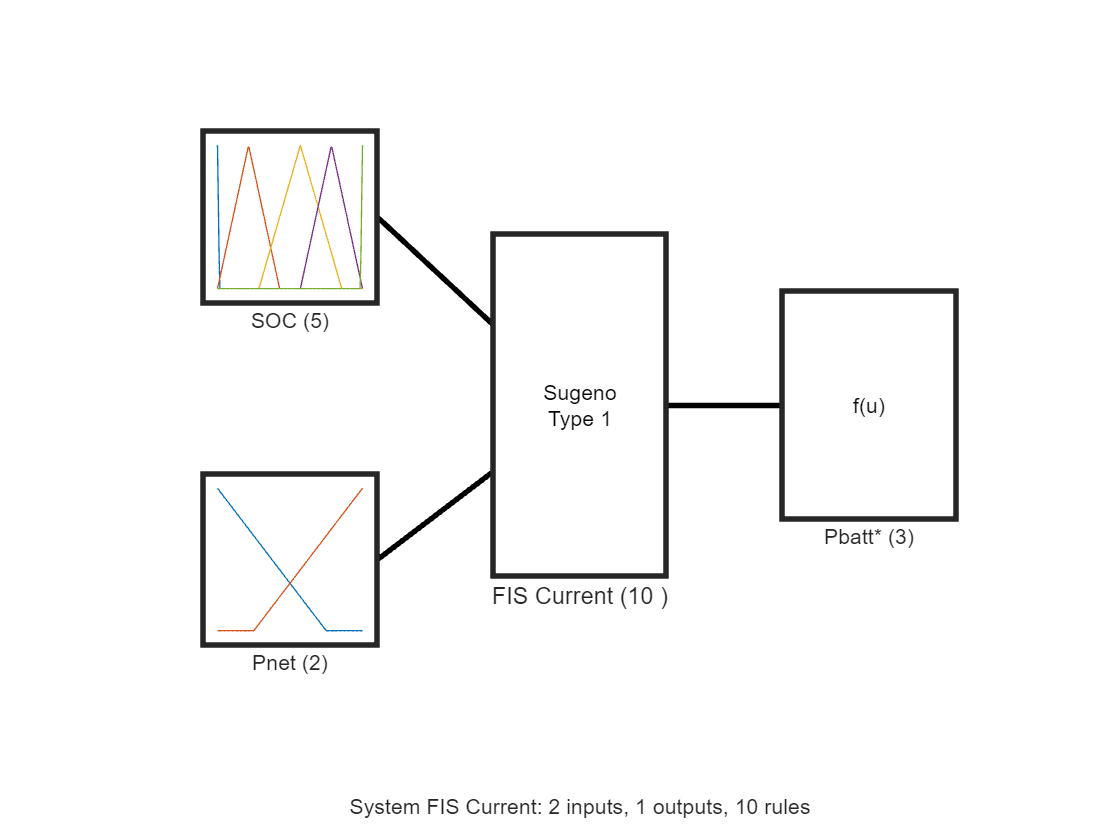

% Output 1
Batt_power_range = [-1 1]; % or  [-battery_max_charge battery_max_discharge]

sugeno =  true;

if sugeno
    % Sugeno Output
    fis_Current = updateOutput(fis_Current,1,'Pbatt*', Batt_power_range, mf_Pbatt);
    fis_Current.Output(1).MembershipFunctions(1).Type = 'constant';
    fis_Current.Output(1).MembershipFunctions(1).Parameters = [Batt_power_range(1)];
    fis_Current.Output(1).MembershipFunctions(2).Type = 'constant';
    fis_Current.Output(1).MembershipFunctions(2).Parameters = [0];
    fis_Current.Output(1).MembershipFunctions(3).Type = 'constant';
    fis_Current.Output(1).MembershipFunctions(3).Parameters = [Batt_power_range(2)];
else
    %Mangani
    fis_Current = updateOutput(fis_Current,1,'Pbatt*', Batt_power_range, mf_Pbatt);
    fis_Current.Output(1).MembershipFunctions(1).Type = 'linzmf';
    fis_Current.Output(1).MembershipFunctions(1).Parameters = [Batt_power_range(1) 0];
    fis_Current.Output(1).MembershipFunctions(2).Type = 'trimf';
    fis_Current.Output(1).MembershipFunctions(2).Parameters = [-0.1 0.1];
    fis_Current.Output(1).MembershipFunctions(3).Type = 'linsmf';
    fis_Current.Output(1).MembershipFunctions(3).Parameters = [0 Batt_power_range(2)];
end

figure
plotfis(fis_Current)

Add Rules

% Clear all Rules
fis_Current.Rules = [];
% Add the rules to the FIS.
rule1 = "If SOC is Min and Pnet is RES>> then Pbatt* is CH";
rule2 = "If SOC is Max and Pnet is Load>> then Pbatt* is DC";
rule3 = "If SOC is Max and Pnet is RES>> then Pbatt* is HOLD";
rule4 = "If SOC is Min and Pnet is Load>> then Pbatt* is HOLD";
rule5 = "If SOC is High and Pnet is RES>> then Pbatt* is CH";
rule6 = "If SOC is High and Pnet is Load>> then Pbatt* is DC";
rule7 = "If SOC is Low and Pnet is RES>> then Pbatt* is CH";
rule8 = "If SOC is Low and Pnet is Load>> then Pbatt* is DC";
rule9 = "If SOC is Medium and Pnet is RES>> then Pbatt* is CH";
rule10 = "If SOC is Medium and Pnet is Load>> then Pbatt* is DC";

rules = strings(1, 10); % ADD ALL Rules 

for i = 1:size(rules,2)
    rulenumber = sprintf('rule%d', i);
    rules(i) = eval(rulenumber);
end
fis_Current = addRule(fis_Current,rules);

##  HELPER FUNCTION

function fis = updateInput(fis,id,name,range,mfNames)
% Update FIS input with the specified parameter values.

fis.Inputs(id).Name = name;
fis.Inputs(id).Range = range;

for mfId = 1:length(mfNames)
    fis.Inputs(id).MembershipFunctions(mfId).Name = mfNames(mfId);
    params = range(1) + ...
        diff(range)*fis.Inputs(id).MembershipFunctions(mfId).Parameters;
    fis.Inputs(id).MembershipFunctions(mfId).Parameters = params;
end

end

function fis = updateOutput(fis,id,name,range,mfNames)
% Update FIS output with the specified parameter values.

rangeDiff = diff(range);
fis.Outputs(id).Name = name;

% MF names - Very Low, Low, Medium, High, Very High
%mfNames = ["VL","L","M","H","VH"];

for mfId = 1:length(mfNames)
    fis.Outputs(id).MembershipFunctions(mfId).Name = mfNames(mfId);
    params = range(1) + ...
        rangeDiff*fis.Outputs(id).MembershipFunctions(mfId).Parameters;
    fis.Outputs(id).MembershipFunctions(mfId).Parameters = params;
end

% Extend output range values to fit the output MFs.
left = fis.Outputs(id).MembershipFunctions(1).Parameters(1);
right = fis.Outputs(id).MembershipFunctions(end).Parameters(end);
fis.Outputs(id).Range = [left right];

end

